I = imread("img\bob.JPG")

I_r = zeros(size(I,1),size(I,2),size(I,3));
I_r(:,:,1) = I(:,:,1);
I_g = zeros(size(I,1),size(I,2),size(I,3));
I_g(:,:,2) = I(:,:,2);
I_b = zeros(size(I,1),size(I,2),size(I,3));
I_b(:,:,3) = I(:,:,3);


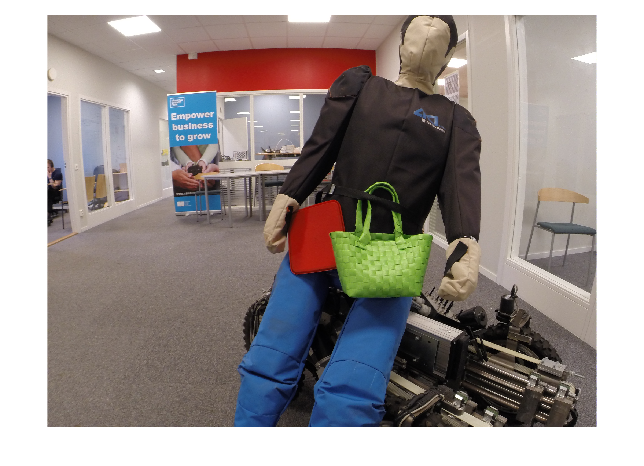


imshow(I)

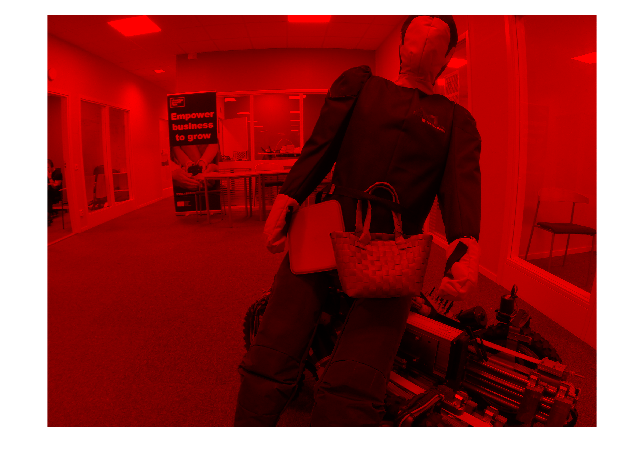

imshow(I_r/255)%Red

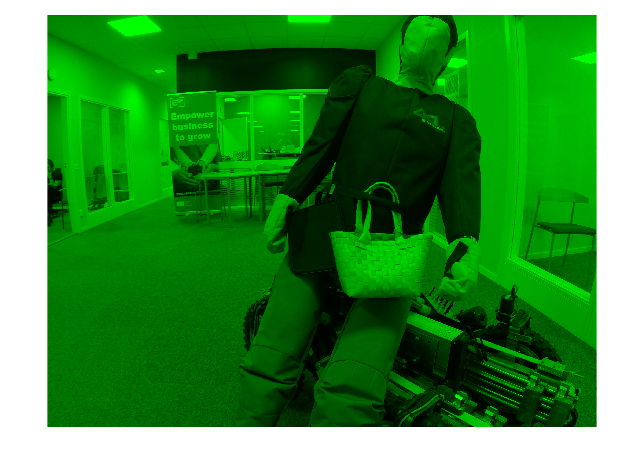

imshow(I_g/255)%Gree

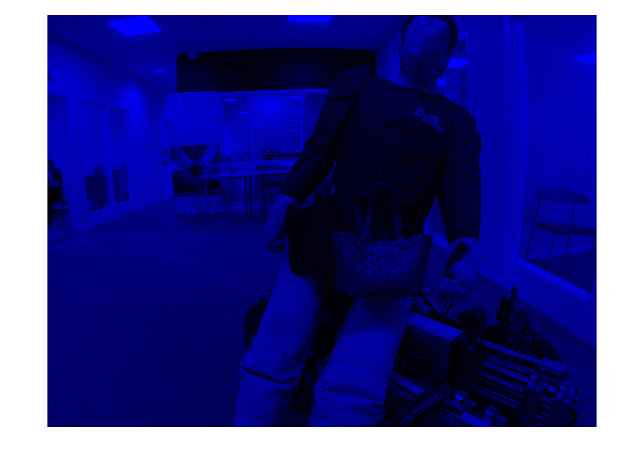

imshow(I_b/255)%Blue

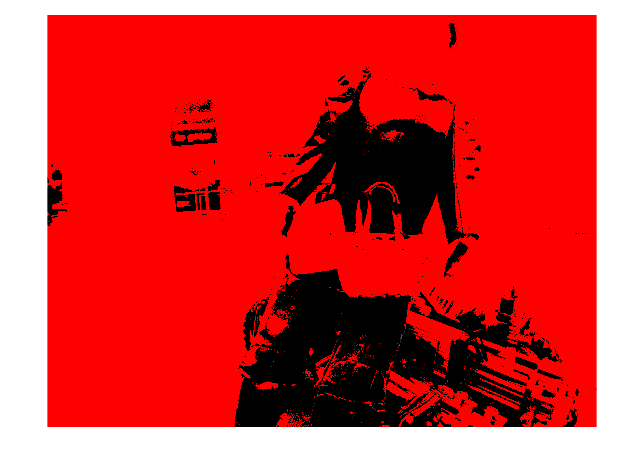

threshold = 0.5;
I_r_thres = 1.*(I_r/255>threshold);
imshow((I_r_thres))%Red

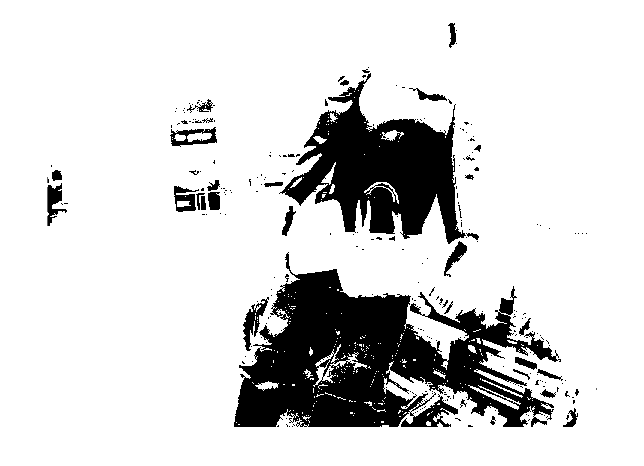

imshow((I_r_thres(:,:,1)))%Red(B/W)

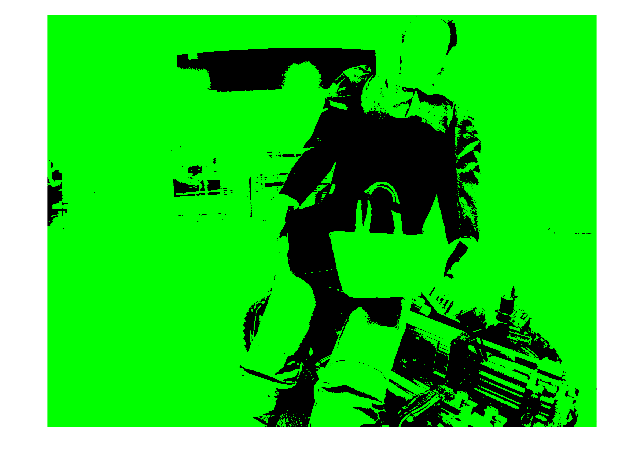

I_g_thres = 1.*(I_g/255>threshold);
imshow((I_g_thres))%Green

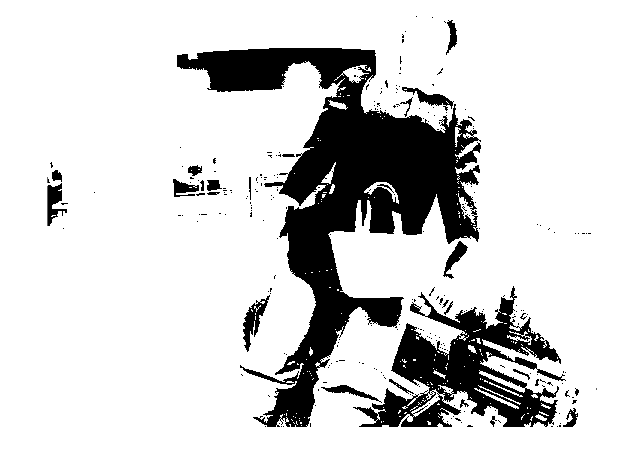

imshow((I_g_thres(:,:,2)))%Green(B/W)

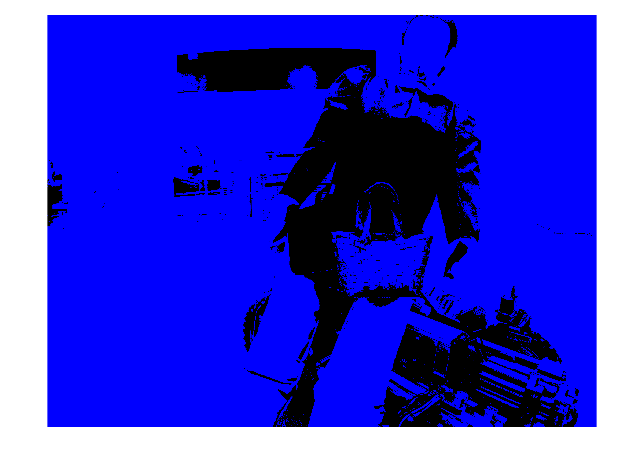

I_b_thres = 1.*(I_b/255>threshold);
imshow((I_b_thres))%Blue

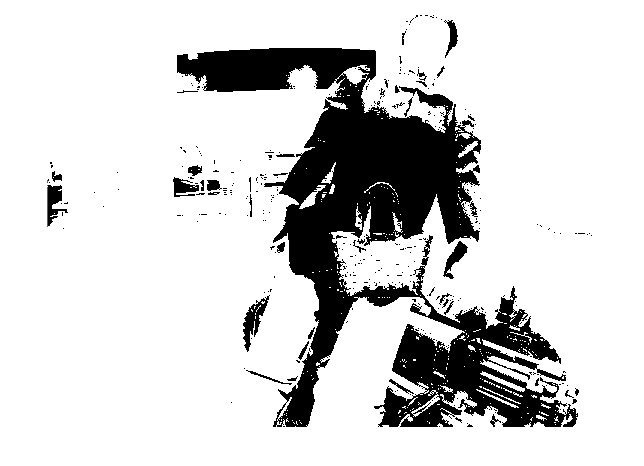

imshow((I_b_thres(:,:,3)))%Blue(B/W)

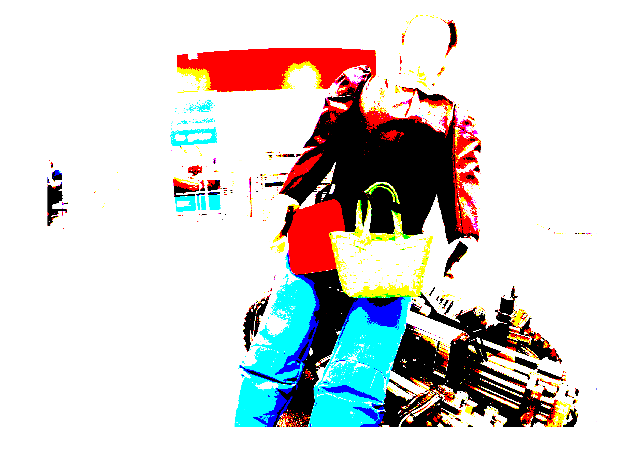

imshow(I_r_thres + I_b_thres + I_g_thres)

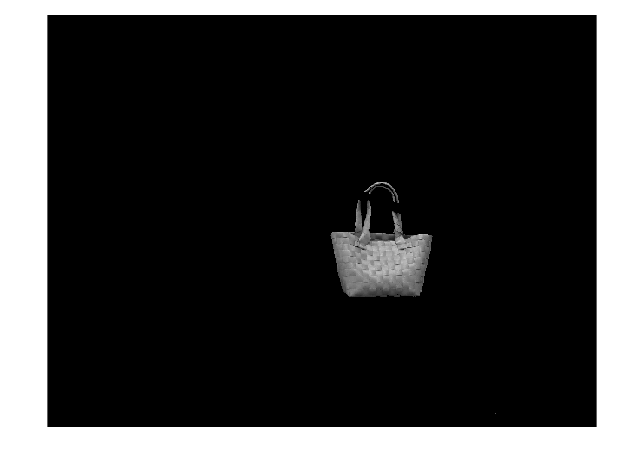

imshow(maskedRGBImage(:,:,1))

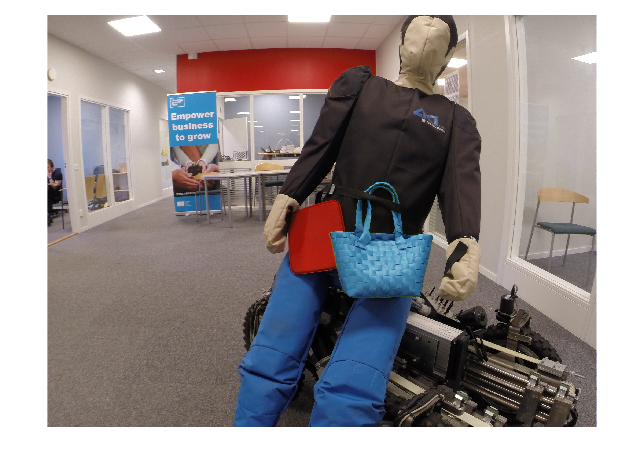

I_n = I;
 
mask_p = uint8(maskedRGBImage(:,:,2) >= 50);
mask_n = uint8(maskedRGBImage(:,:,2) < 50);

I_n = I_n.*mask_n;
for i = 1:3
    I_n(:,:,mod(i,3)+1) = I_n(:,:,mod(i,3)+1) + maskedRGBImage(:,:,mod(i-1,3)+1).*mask_p;
end
imshow(I_n)